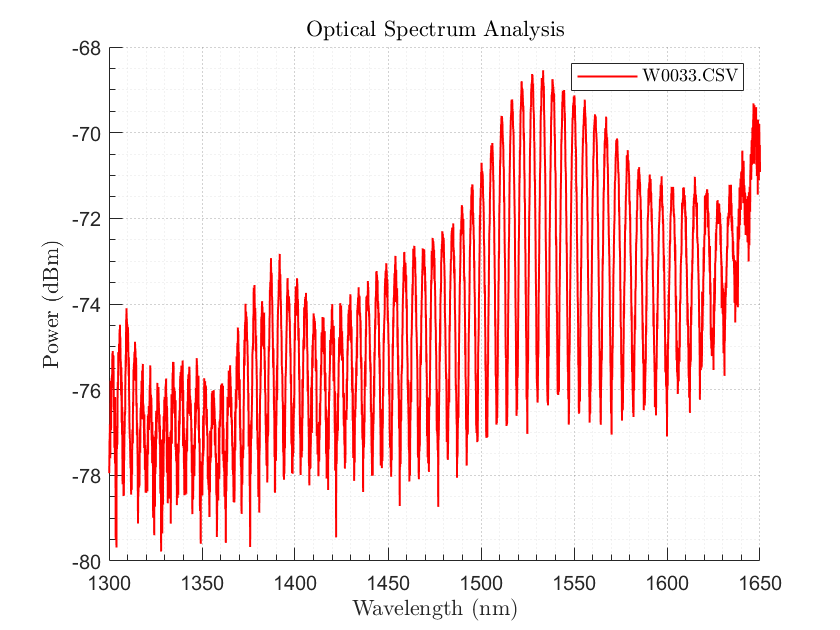

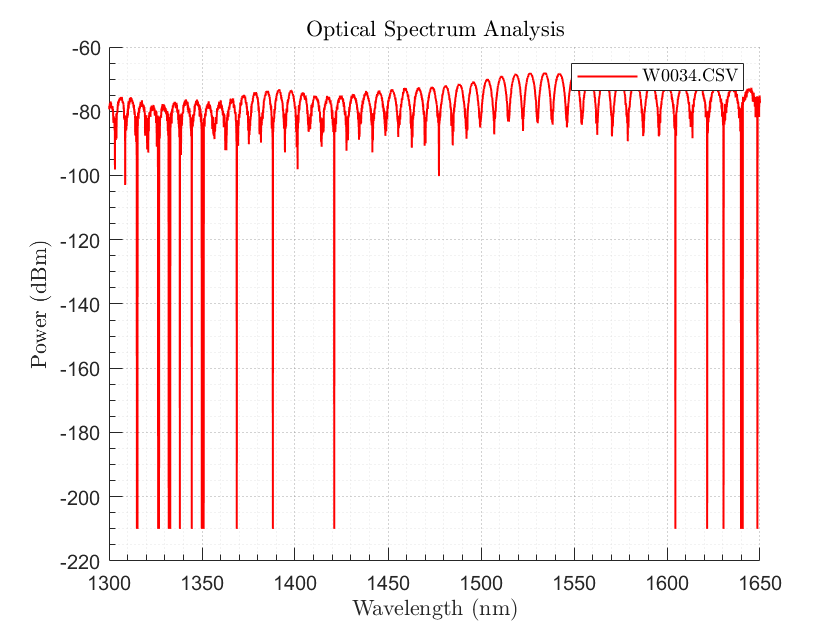

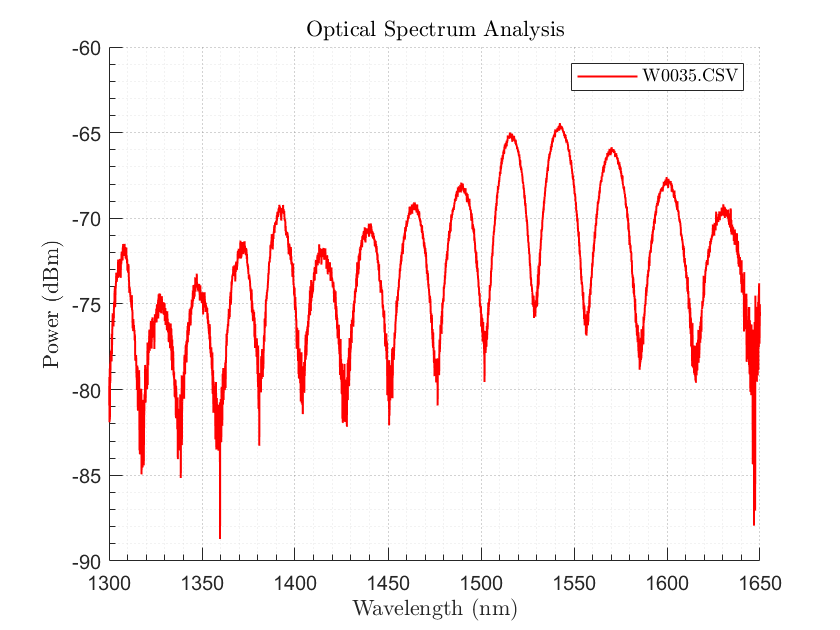

clear;
cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

fileNames = { 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0033.CSV'
     'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0034.CSV' 
      'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0035.CSV' };

% Loop through each file and generate a unique output name
for i = 1:length(fileNames)
    plotOpticalSpectra(fileNames{i});  % Ensure correct indexing with {}
    f = gcf();
    
%     % Generate unique file name
%     outputFileName = sprintf('SCGLab_%02d.png', i);
%     
%     % Export the figure with the unique name
%     exportgraphics(f, outputFileName);
end

function plotOpticalSpectra(fileNames)
% plotOpticalSpectra Reads and plots optical spectrum data from CSV files.
%
%   plotOpticalSpectra(fileNames) reads each CSV file specified in the
%   cell array of filenames, removes the first 21 elements from the wavelength
%   and power columns, and plots the processed data in a new figure.
%
%   Input:
%       fileNames - A cell array or string array of full paths to CSV files.
%
%   Example:
%       fileNames = { 'C:\Path\To\W0002.CSV', 'C:\Path\To\W0003.CSV' };
%       plotOpticalSpectra(fileNames);

    % Ensure fileNames is a cell array of strings
    if ~iscell(fileNames)
        fileNames = cellstr(fileNames);
    end

    nFiles = numel(fileNames);
    
    % Generate distinct colors:
    if nFiles == 1
        colors = [1 0 0];  % Use preset colors for 2 files
    else
        colors = hot(nFiles);     % Use a colormap for more files
    end

    % Create figure and hold on for multiple plots
    figure;
    hold on;
    
    % Prepare legend entries
    legendEntries = cell(nFiles, 1);
    
    for i = 1:nFiles
        % Read data from CSV file
        data = readmatrix(fileNames{i});
        
        % Extract wavelength and power columns
        wavelength = data(:, 1);
        power = data(:, 2);
        
        % Remove the first 21 elements from both vectors
        wavelength(1:21) = [];
        power(1:21) = [];
        
        % Plot the data with a unique color from the i-th row
        plot(wavelength, power, 'LineWidth', 1.02, 'Color', colors(i, :));
        
        % Create legend entry using the file name (without full path)
        [~, name, ext] = fileparts(fileNames{i});
        legendEntries{i} = [name, ext];
    end

    % Configure plot appearance
    xlabel('Wavelength (nm)', 'Interpreter', 'latex');
    ylabel('Power (dBm)', 'Interpreter', 'latex');
    title('Optical Spectrum Analysis', 'Interpreter', 'latex');
    grid on;
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
             'TickLength', [0.02, 0.04], 'LineWidth', 0.5);
    grid minor;
    set(gca, 'GridLineStyle', ':', 'GridColor', [0.5, 0.5, 0.5], ...
             'GridAlpha', 0.7, 'MinorGridLineStyle', ':', ...
             'MinorGridColor', [0.8, 0.8, 0.8], 'MinorGridAlpha', 0.5);
    
    % Add a legend using file names
    legend(legendEntries, 'Interpreter', 'latex');
    hold off;
end
